# Testing Platform for electron optics formulas

clear;
clf;
% % Tells me if code has excecuted already without clearing
% if ~exist('VarName','var')
% VarName=0;
% end

cd('C:\Users\johns\Documents\Github\QEM-MATLAB\Electron Optics');
addpath('C:\Users\johns\Documents\Github\QEM-MATLAB');
load("ImpVariables.mat");

## CONTROL

E_simple_plate = 1;     %Plot electric feilds?
B_simple_loop = 0;      %Plot magnetic fields?
plotRes = 0;            %Whether or not we plot the resolution limit of a streak camera
plotTrajectories = 1;   %Whether or not we plot the trajectories or just the final position
legString = [];


## Simple Electric Calculator

% Electric Variables
    length = 550*c.milli; % mm distance to phosphor
    D = 23 * c.milli; %mm plates length 50ohm 23mm
    W = 5* c.milli;  %mm plate sepearation 50hm 5mm
    Vd = 1; %volts across plate deflector
    Vl = 1000; %voltage of high tension extractor (beam energy)

deflE = Deflector(D, W, length, Vd, Vl)/c.milli % in mm

deflE = 1.2915

## Variables

% Plotting variables 
    x_start = 0 * c.milli; %mm
    x_res = 0.1 * c.milli;
    x_max = 550 * c.milli; % 550mm from port to bottem

% Electric Variables
    D = 23 * c.milli; %mm plates length 50ohm 23mm
    W = 5* c.milli;  %mm plate sepearation 50hm 5mm
    Vd = 1; %volts across plate deflector
    Vl = 5000; %voltage of high tension extractor (beam energy)

    var2add = Vl;
    legString = [legString var2add];
% Magnetic Variables
    I = 1 *c.milli; %forcing to mA
    R = 3 *c.milli; %loop radius forcing to mm
    N = 50; %# of loops
    ur = 100; %Relative mu used
    mu = c.u0_SI*ur;
    
% Plotting array generator
if (plotTrajectories==1)
    x = x_start:x_res:x_max;
    n = size(x);
    n = n(2);
else
    x = x_max
    n=1;
end
% if ~VarName
%     soln = x;
% end

## Plot parallel plate electron trajectories

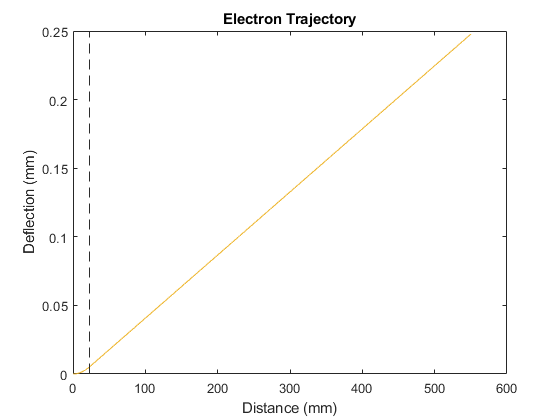

%units all work out without scaling
if (E_simple_plate == 1)

    for i = 1:n
        if (x(i)>D)
            deflE(i) = Deflector(D, W, x(i)-D, Vd, Vl);
        else
            deflE(i) = Deflector(x(i), W, 0, Vd, Vl);
        end
    end
    
    if (plotTrajectories==1)
        figure(1)
        plot(x/c.milli, deflE/c.milli);
        title('Electron Trajectory')
        xlabel('Distance (mm)');
        ylabel('Deflection (mm)');
        divider = xline(D/c.milli,'--');
        hold on
    end
    
    %Plots MCP resolution
    if (plotRes == 1)
        pixelSize = 25*c.micro; % Assumed size of pixel/MCPs spatially
        nPixels = deflE/pixelSize; %plot of number of pixels available
        tSweep = 8*c.nano; %nanoseconds
        xResStart = 10*c.milli; %x axis plot range start
        timeRes = tSweep./nPixels;

        figure (2)
        semilogy(x/c.milli, timeRes/c.nano);
        title('Temporal Resolution')
        xlabel('Distance (mm)');
        ylabel('Resolution (ns)');
        divider = xline(D/c.milli,'--');
        xlim([xResStart/c.milli x_max/c.milli]);
        grid minor;
        hold on;
    end
end

## Plot Magnetic Deflection (simple perfect field)trajectories

if (B_simple_loop == 1);
    B_loop = mu*N*I/(2*R); %Tesla
    B = B_loop; %Simple override for electron in constant feild flat region
    L = 2*R;    %simply model of loop length
    r = sqrt(2*c.me_SI/c.e_SI) * sqrt(Vl)/B ; %radius of curvature (m) for electron in B feild

    defl_exit = (r - sqrt(r^2 - L^2)); %Circular exit point

    % plots out trajectories
    for i = 1:n

        if (x(i)<L)
            deflB(i) = r - sqrt(r.^2 - (x(i))^2);
        else
            deflB(i) = defl_exit + (x(i)-L)*L/(r-defl_exit);            
        end
    end

    %hold on;
    if (plotTrajectories==1)
        Vst = "Vlen=" + num2str(Vl) + " V";
        Bst = ""; %" Bloop=" + num2str(B_loop) + " T";
        figure(3)
        plot(x/c.milli, deflB/c.micro, 'DisplayName', Vst+Bst);
        %divider = xline(L/c.milli,'--');
        legend('-DynamicLegend');
        title('Magnetic Electron Trajectory')
        xlabel('Distance (mm)');
        ylabel('Deflection (um)');
    end
    

end


## Double Deflector Math/Beam Shift

% Edefl_Shift = 2*deflE(end)/c,milli; %In mm
Bdefl_Shift = 2*deflB(end)/c.milli %in mm

The end operator must be used within an array index expression.